# Sin Function Test

## Clear Workspace

close all; clearvars; clc;

## Vars

N = 500e3; % sets the length of buffer for preloading
sample_HZ = 1e6; % frequency HZ
A = 0.5; % amplitude p-pk V
duration = 0.5;
f1 = 10e3; % lowest frequency component Hz
f2 = 30e3; % mid frequency component Hz
f3 = 50e3; % highest frequency component Hz
phase = pi; % phase of the system in degrees


## Wave Gen Function

% new
periods = 1/eval(gcd(sym([f1 f2 f3]))); % calculates the length of the period for a periodic
timeStep = 1/sample_HZ; % period of the sampling frequency
t = (0:timeStep:periods-timeStep)'; % calculates the time vector from the period

y = A*sin(2*pi*f1*t+phase) + A*sin(2*pi*f2*t+phase) + A*sin(2*pi*f3*t+phase); % calculates the signal along the time vector
numCycles = ceil(N/length(y)); % calculate the number of cycles to make a full buffer for preloading
sine = repmat(y, numCycles, 1); % extends the data vector to match or execed the buffer length

## Plot Waves

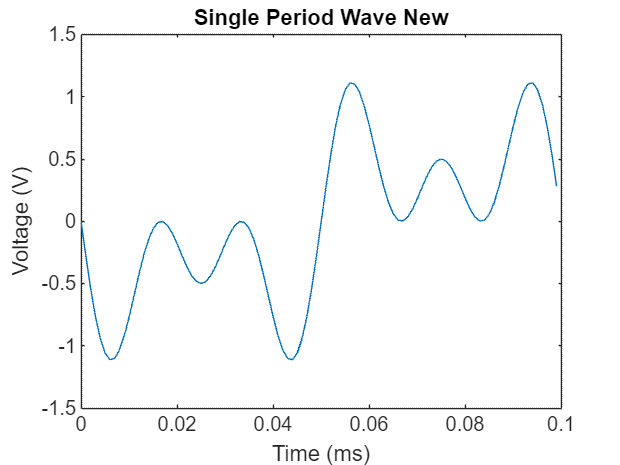

figure
plot(t*1e3, y)
ylabel('Voltage (V)')
xlabel('Time (ms)')
title('Single Period Wave New')

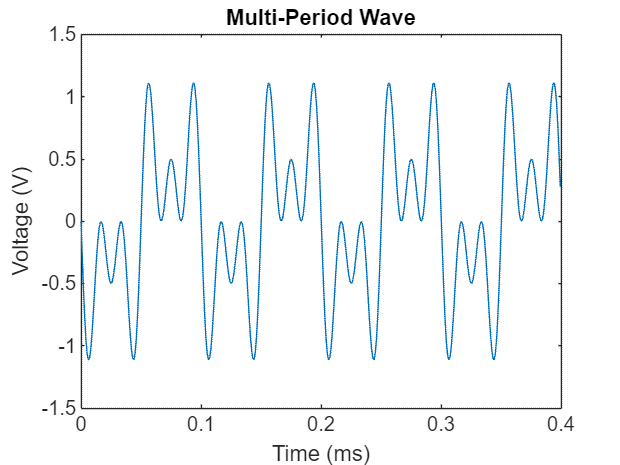


t1 = (0:timeStep:periods*4-timeStep)';
points = floor((periods/timeStep)*4);
figure
plot(t1*1e3, sine(1:points))
ylabel('Voltage (V)')
xlabel('Time (ms)')
title('Multi-Period Wave')

## Plot FFT

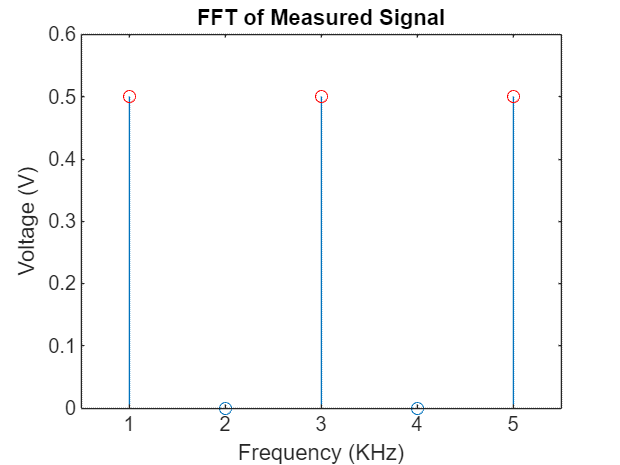

FFT_signal = fft(y, round(periods/timeStep));
f_HZ1 = ((0:(periods/timeStep)-1)*sample_HZ)/(periods/timeStep);
figure;
stem(f_HZ1/1e4, abs(FFT_signal)/(periods/timeStep)*2)
title('FFT of Measured Signal')
ylabel('Voltage (V)')
xlabel('Frequency (KHz)')
hold on
plot(f1/1e4, 0.5, 'r o', f2/1e4, 0.5, 'r o', f3/1e4, 0.5, 'r o')
xlim([(f1/1e4-0.5*f1/1e4) (f3/1e4+0.5*f1/1e4)])
ylim([0 0.6])